# Guião 5

## I . Amostragem e reconstrução de sinais

## Exercicio 1 - Função que reconstroi o sinal a partir de uma sequencia de amostras

% função no fim


## Exercicio 2

% a)
fprintf("2. a)")

2. a)

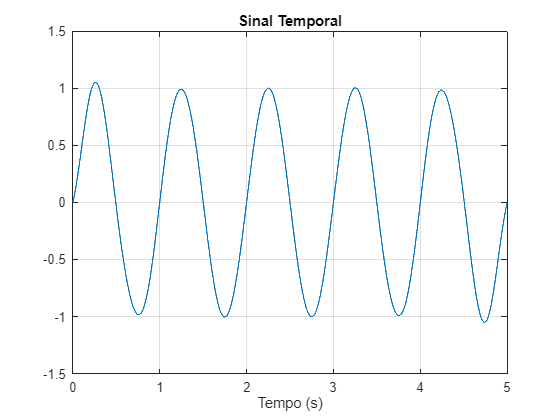


Ta = 0.2;
t = 0:Ta:5-Ta;

x = sin(2*pi*t);
[y, t] = ReconstroiSinal(x,Ta);

plot(t,y)
xlabel("Tempo (s)")
title("Sinal Temporal")
grid;


% ------------------------------

% b)
fprintf("2. b)")

2. b)

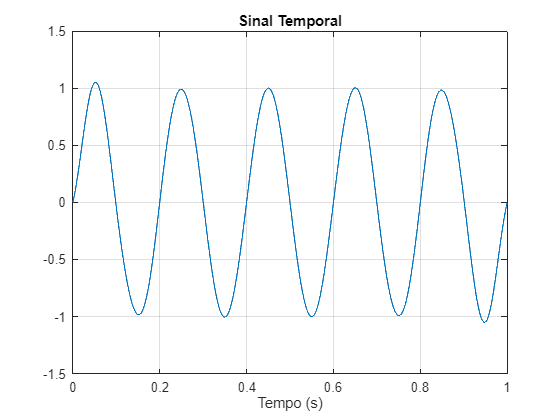


Ta = 0.04;
t = 0:Ta:5-Ta;

y = sin(10 * pi * t) + cos(12 * pi * t) + cos(14 * pi * t - pi/4);
[y, t] = ReconstroiSinal(x,Ta);


plot(t,y)
xlabel("Tempo (s)")
title("Sinal Temporal")
grid;

## II. Quantização da Amplitude dos Sinais

## Exercicio 1 - Quantização da amplitude de um sinal. Comparação com sinal original

fprintf("II 1.")

II 1.

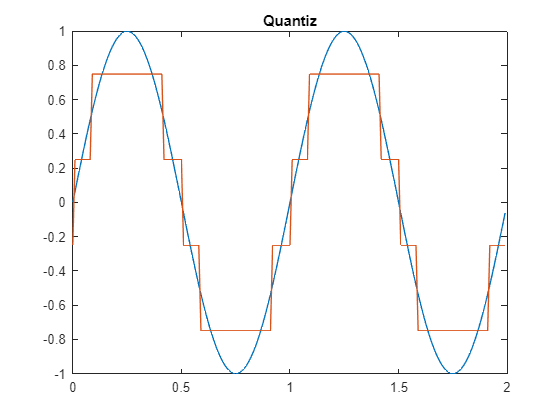


Ta = 0.01;	                                        % periodo de amostragem
t = (0 : Ta : 2-Ta)';                               % vetor tempo

x = sin(2*pi*t);          

nbit = 2;                                           % numero de bits de quantização
amp=2*max(abs(x));                                  % calcula amplitude maxima, e duplica para obter a amplitude completa
Npal = 2^nbit;                                      % numero de bits de quantização. 1 bit representa dois estados (0 ou 1)
Delta = amp/Npal;                                   % tamanho do passo de quantização

partition = [-1+2*Delta/2 : Delta : 1-Delta/2];     % vetor partição com limites entre niveis de quantização
                                                    % estes valores representam os thresholds onde o quantizador muda de nivel

codebook = [-1+Delta/2 : Delta : 1-Delta/2];        % vetor com os valores de saida quantizados correspondentes a cada intervalo em partition  
% cada valor de codebook é o valor específico que será utilizado para representar o sinal numa determinada faixa de amplitude

[index,quants] = quantiz(x,partition,codebook);     % esta linha aplica quantização ao sinal
% index é um vetor que indica que o respetivo intervalo de partition que cada elemento de x pertence
% quants é a versão quantizada do sinal x, em que cada valor em x é trocado pelo valor quantizado correspondente 

figure(1);
plot(t,x,t,quants);
title("Quantiz")



fprintf("Exercicio 2")

Exercicio 2

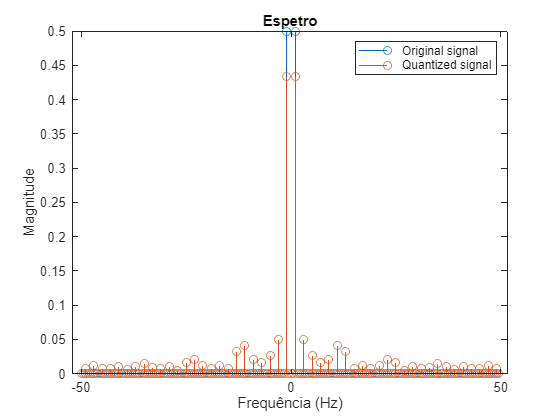


[X,f] = Espetro(x,Ta);
legend("Original Signal");
hold on;

[X,f] = Espetro(quants,Ta);
legend("Quantized Signal");
hold off;
legend("Original signal", "Quantized signal");


fprintf("Exercicio 3")

Exercicio 3

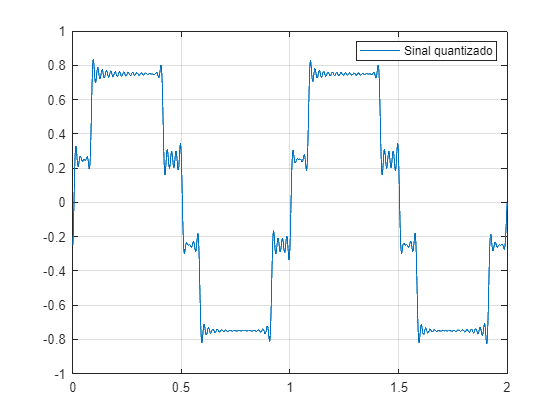


[y, t] = ReconstroiSinal(quants, Ta);
plot(t, y)
legend("Sinal quantizado");
grid

## Funções

function [y, t] = ReconstroiSinal(x, Ta)
    %
    %   x : vetor com amostras dos sinais
    %   Ta : periodo de amostragem
    %
    %   y : sinal reconstruido 
    %   t : instantes de tempo correspondentes ás amostras

    N = length(x);          % número de amostras
    Fa = 1/Ta;              % frequencia de amostragem
    Fs = 100 * Fa;          % frequencia do sinal
    
    y = zeros(100*N,1);     
    
    t = (0 : (length(y)-1))' * (1/Fs);      %intervalo de zero ao ultimo ponto de y com passo 1/Fs

    for n = 1:N
        y = y + x(n)*sinc(Fa*(t-(n-1)*Ta));
    end
end

function [X, f] = Espetro(x, Ta) 
    % Inputs:
    % x - dimensão do vetor
    % Ta - Periodo de amostragem
    %
    % Outputs:
    % X - vetor da mesma dimensão de x, com coeficientes da dft de x(t)
    % f - vetor da mesma dimensão de x, com as frequências de cada componente
    % de X
    
    Fa = 1 / Ta;                % freq de amostragem
    N = length(x);              % numero de amostras
    
    % fft(x) calcula a dft de x : devolve um
    % vetor complexo que representa amplitude e
    % as fases das componentes das freqs do sinal

    X = fftshift(fft(x))/N;         % fft(x)/N normaliza a dft, para obter amplitude media de cada componente      

    % fftshift reorganiza os valores dos vetores de X para centralizar
    % as frequências em torno de zero

    % resolução frequencia (espaçamento entre amostras de frequência)
    delta_f = Fa / N;
    
    f = (-N/2:N/2-1)*(delta_f);       % vetor de frequencias
    %  cobre o intervalo de -Fa/2 a Fa/2 em passos de delta_f.
                                
                                % abs(x) vai calcular a magnitude de cada
                                % componente
    stem(f, abs(X));            % grafico do tipo haste das magnitudes de em função das frequencias
    xlabel("Frequência (Hz)")
    ylabel("Magnitude")
    title("Espetro")
    grid;

end